# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 16-May-2020 17:55:09

## Carregar les dades

trainData = datastore("..\input\RebeloDataset\Dataset", "IncludeSubfolders",true, "LabelSource","foldernames");

[trainData, valiData] = splitEachLabel(trainData, 0.7);

trainData = transform(trainData, @binarizeValidation, "IncludeInfo", true);
valiData = transform(valiData, @binarizeValidation, "IncludeInfo", true);

read(valiData)

ans = 1×2 cell array
    {20×20 logical}    {[Accent]}


## Create the Array of Layers

layers = [
    imageInputLayer([20 20 1],"Name","imageinput")
    convolution2dLayer([3 3],8,"Name","conv_1","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    convolution2dLayer([3 3],8,"Name","conv_2","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    convolution2dLayer([3 3],32,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    fullyConnectedLayer(52,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Plot the Layers

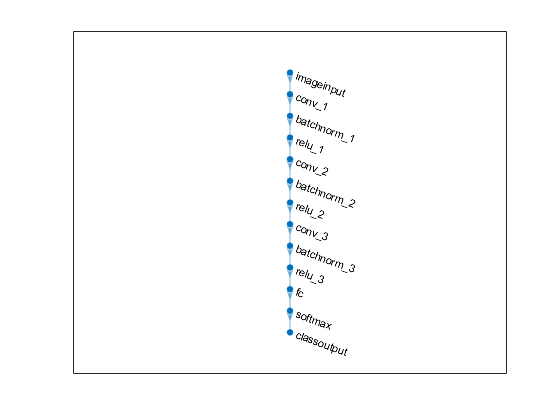

plot(layerGraph(layers));

## Opcions de training

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData', valiData, ...
    'ValidationFrequency',30, ...
    'Verbose',true, ...
    'Plots','training-progress');

## Entrena

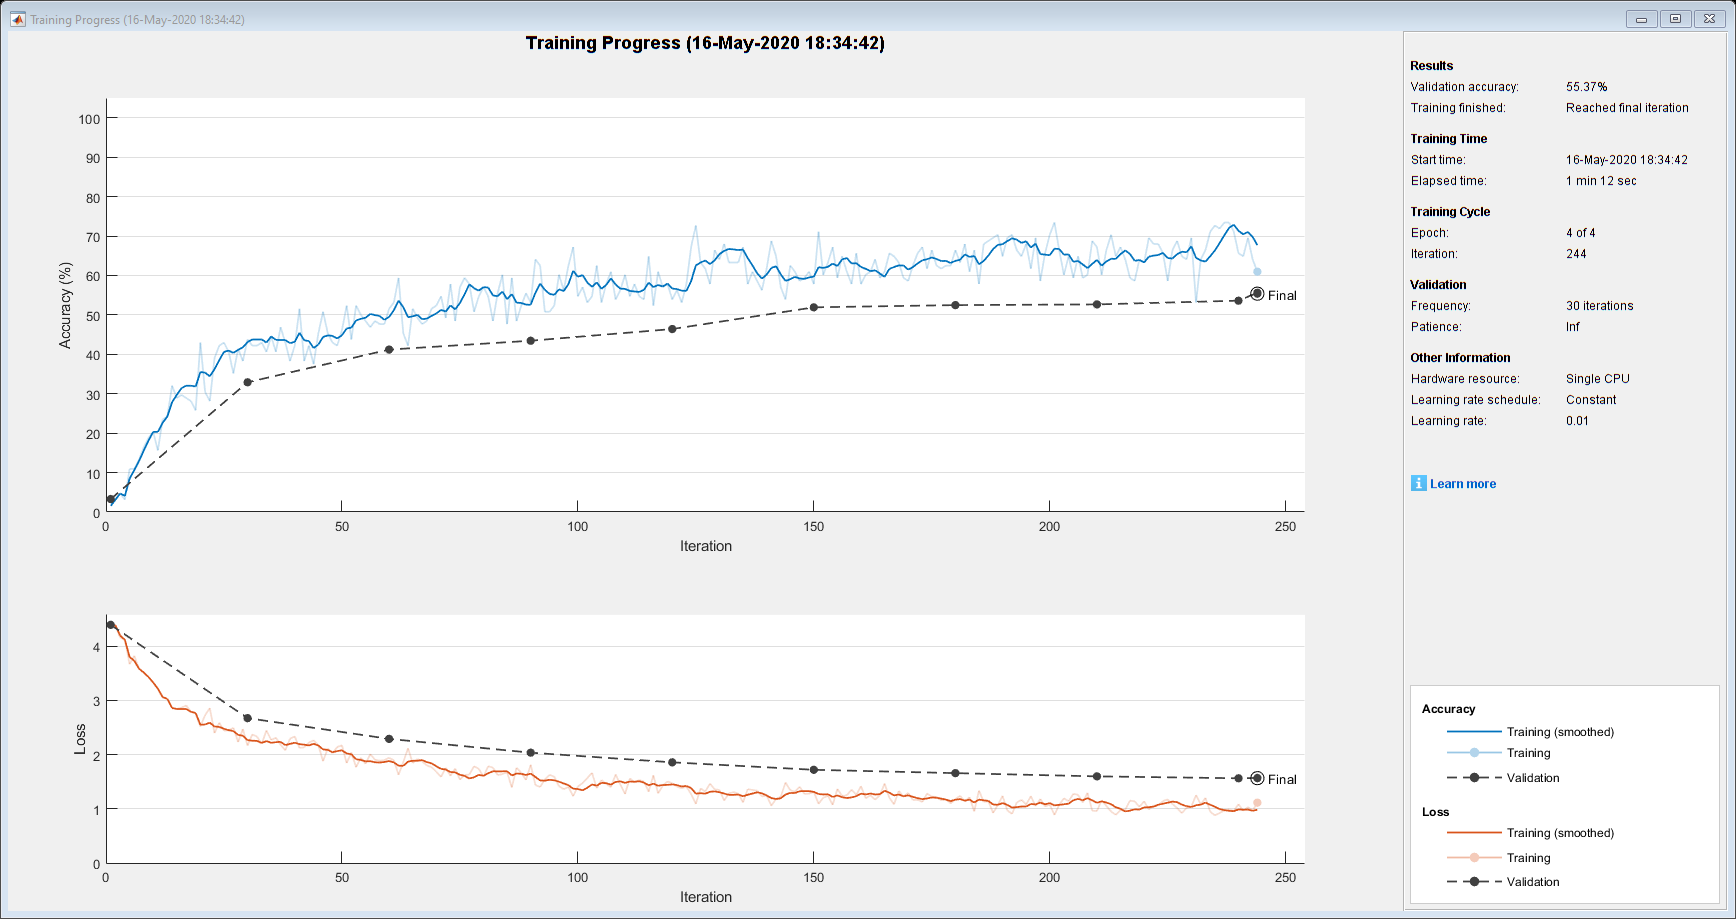

xarxa = trainNetwork(trainData, layers, options);